clc; close all; clear all;

s = tf('s');
G = 1/(s+0.6)/(s+0.5)/(s+0.4)/(s+0.3);
K = inv(G)/(s+3);

Gcl = feedback(G*K,1)

Gcl =
 
        s^4 + 1.8 s^3 + 1.19 s^2 + 0.342 s + 0.036
  ------------------------------------------------------
  s^5 + 5.8 s^4 + 8.39 s^3 + 5.102 s^2 + 1.404 s + 0.144
 
Continuous-time transfer function.
Model Properties


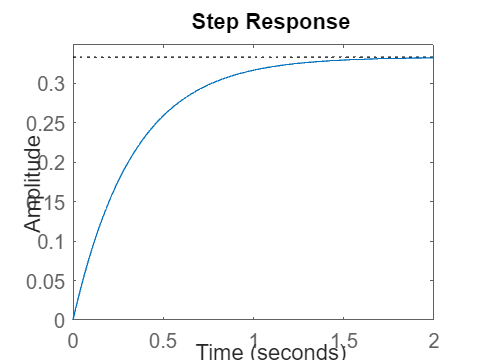

step(K*G)

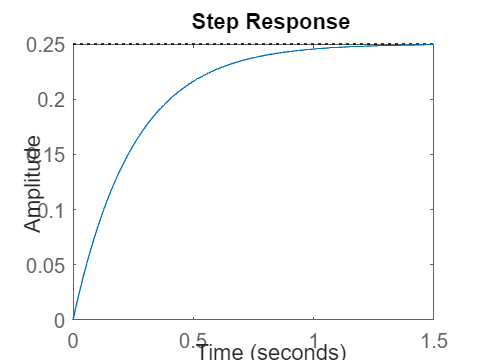

step(Gcl)

%% Control desacoplado 
clc; close all; clear all;
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


G = [1/(4*s+1) 2.5/(15*s+1); 4/(20*s+1) 1/(5*s+1)]

G =
 
  From input 1 to output...
          1
   1:  -------
       4 s + 1
 
          4
   2:  --------
       20 s + 1
 
  From input 2 to output...
         2.5
   1:  --------
       15 s + 1
 
          1
   2:  -------
       5 s + 1
 
Continuous-time transfer function.
Model Properties



Gobj = [1/(0.05*s+1) 0; 0 1/(0.5*s+1)]

Gobj =
 
  From input 1 to output...
           1
   1:  ----------
       0.05 s + 1
 
   2:  0
 
  From input 2 to output...
   1:  0
 
           1
   2:  ---------
       0.5 s + 1
 
Continuous-time transfer function.
Model Properties


C_objetivo = Gobj*(eye(2)- Gobj)^-1

C_objetivo =
 
  From input 1 to output...
          s + 20
   1:  ------------
       0.05 s^2 + s
 
   2:  0
 
  From input 2 to output...
   1:  0
 
               s + 2
   2:  ----------------------
       0.5 s^2 + s + 6.28e-16
 
Continuous-time transfer function.
Model Properties



Cs = inv(G)*C_objetivo

Cs =
 
  From input 1 to output...
       12 s^4 + 244.4 s^3 + 88.39 s^2 + 7.81 s + 0.2
   1:  ---------------------------------------------
        0.05 s^4 + 0.9725 s^3 - 0.5545 s^2 - 0.09 s
 
       -12 s^4 - 246.2 s^3 - 125 s^2 - 19.24 s - 0.8
   2:  ---------------------------------------------
        0.05 s^4 + 0.9725 s^3 - 0.5545 s^2 - 0.09 s
 
  From input 2 to output...
          -10 s^4 - 25 s^3 - 10.73 s^2 - 1.475 s - 0.05
   1:  ----------------------------------------------------
       0.5 s^4 + 0.725 s^3 - 0.595 s^2 - 0.09 s - 5.652e-17
 
           15 s^4 + 34.75 s^3 + 9.9 s^2 + 0.81 s + 0.02
   2:  ----------------------------------------------------
       0.5 s^4 + 0.725 s^3 - 0.595 s^2 - 0.09 s - 5.652e-17
 
Continuous-time transfer function.



GLC = feedback(G*Cs,eye(2))

GLC =
 
  From input 1 to output...
          20 s^37 + 1735 s^36 + 5.899e04 s^35 + 9.799e05 s^34 + 7.99e06 s^33 + 2.742e07 s^32 + 2.028e07 s^31 - 8.82e07 s^30 - 1.473e08 s^29 + 1.168e08 s^28 + 2.881e08 s^27 - 1.015e08 s^26 - 2.751e08 s^25 + 6.743e07 s^24 + 1.311e08 s^23 - 1.338e07 s^22 - 3.84e07 s^21 - 3.097e06 s^20 + 6.527e06 s^19 + 1.897e06 s^18 - 3.807e05 s^17 - 3.044e05 s^16 - 5.065e04 s^15 + 8290 s^14 + 5840 s^13 + 1446 s^12 + 223.8 s^11 + 24.13 s^10 + 1.871 s^9 + 0.1045 s^8 + 0.004112 s^7 + 0.0001082 s^6 + 1.709e-06 s^5 + 1.224e-08 s^4 + 5.79e-23 s^3 - 2.317e-27 s^2 - 8.183e-42 s + 5.412e-56
   1:  ---------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------

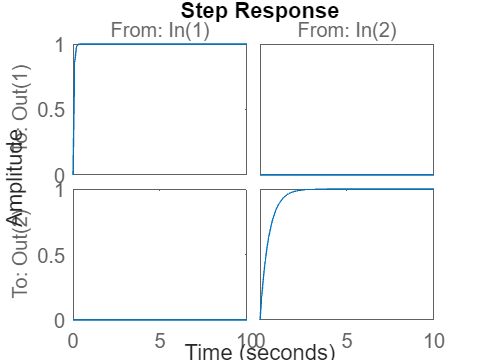

step(GLC,10)


clc; clear all; close all;
A = [-3.32 3.32 0;
    3.32 -3.32-2.67 2.67;
    0 2.67 -2.67-1]

A =    -3.3200    3.3200         0
    3.3200   -5.9900    2.6700
         0    2.6700   -3.6700


B = [1 20 0; 20 1 0; 0 0 1]

B =      1    20     0
    20     1     0
     0     0     1


C = eye(3)

C =      1     0     0
     0     1     0
     0     0     1


D = zeros(3)

D =      0     0     0
     0     0     0
     0     0     0



Gss = ss(A,B,C,D);
G = tf(Gss)

G =
 
  From input 1 to output...
            s^2 + 76.06 s + 258.5
   1:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.864
 
           20 s^2 + 143.1 s + 255.9
   2:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.864
 
                53.4 s + 186.2
   3:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.864
 
  From input 2 to output...
           20 s^2 + 196.5 s + 309.3
   1:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.864
 
            s^2 + 73.39 s + 255.9
   2:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.864
 
                2.67 s + 186.2
   3:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.864
 
  From input 3 to output...
                    8.864
   1:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.864
 
                2.67 s + 8.864
   2:  --------------------------------
       s^3 + 12.98 s^2 + 35.9 s + 8.8

% 1/(T*s+1)
% T*s+1=0 ---> T = -1/s
Gobj = [1/(-1/)]

Unrecognized function or variable 's'.

C_objetivo = Gobj*(eye(2)- Gobj)^-1

Cs = inv(G)*C_objetivo
GLC = feedback(G*Cs,eye(2))
step(GLC,10)

Gss = ss(A,B,C,D);
Gs = tf(Gss)